clear all
close all
clc
data = readtable("results\result.csv");

data.avg_run = data.runTimeInMs./data.sampleSize;
data.run(:) = "parallel";
data_full = readtable("results\timed_measurement_c_p_data.csv");

data_full.avg_run = data_full.runTimeInMs./data_full.sampleSize;
data_paralell = data_full(data_full.parallel == true,:);
data_serial = data_full(data_full.parallel == false,:);
data_paralell.run(:) = "párhuzamos";
data_serial.run(:) = "soros";

figure
subplot(1,2,1)
%boxplot(data.runTimeInMs,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.runTimeInMs,data_paralell.sampleSize,"LabelOrientation",'inline')
title("Párhuzamos futási idők")
set(gca, 'YScale', 'log')
ylabel("mikroszekundum")

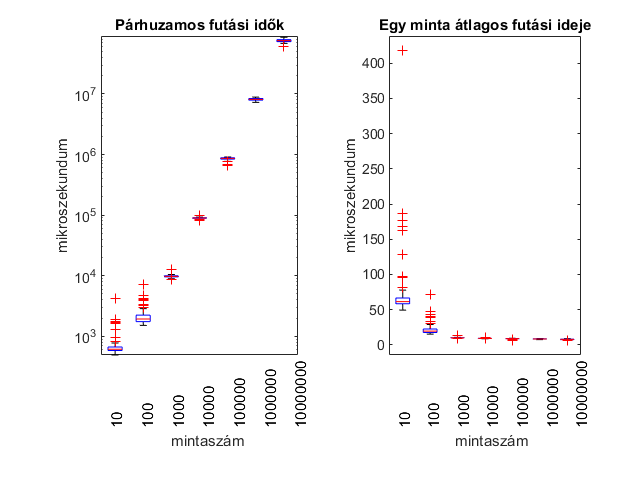

xlabel("mintaszám")
subplot(1,2,2)
%boxplot(data.avg_run,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.avg_run,data_paralell.sampleSize,"LabelOrientation",'inline')
title("Egy minta átlagos futási ideje")
ylabel("mikroszekundum")
xlabel("mintaszám")

figure

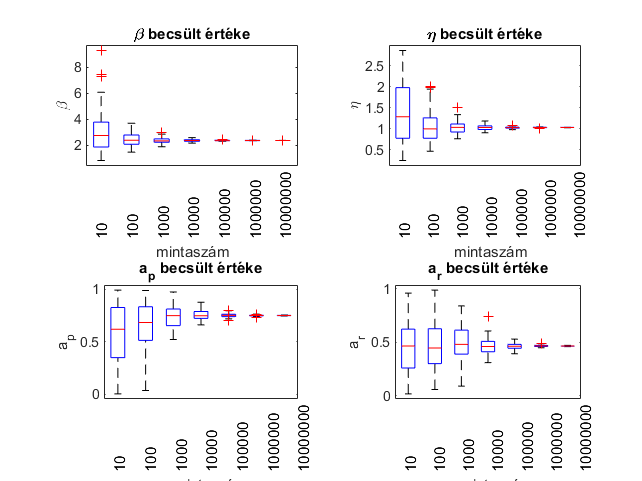

title("paraméterek becsült értéke")
subplot(2,2,1)
%boxplot(data.beta,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.beta,data_paralell.sampleSize,"LabelOrientation",'inline')
title("\beta becsült értéke")
ylabel("\beta")
xlabel("mintaszám")
subplot(2,2,2)
%boxplot(data.eta,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.eta,data_paralell.sampleSize,"LabelOrientation",'inline')
title('\eta becsült értéke')
ylabel("\eta")
xlabel("mintaszám")
subplot(2,2,3)
%boxplot(data.ap,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.ap,data_paralell.sampleSize,"LabelOrientation",'inline')
title('a_{p} becsült értéke')
ylabel("a_{p}")
xlabel("mintaszám")
subplot(2,2,4)
%boxplot(data.ar,data.sampleSize,"LabelOrientation",'inline')
boxplot(data_paralell.ar,data_paralell.sampleSize,"LabelOrientation",'inline')
title('a_{r} becsült értéke')
ylabel("a_{r}")
xlabel("mintaszám")

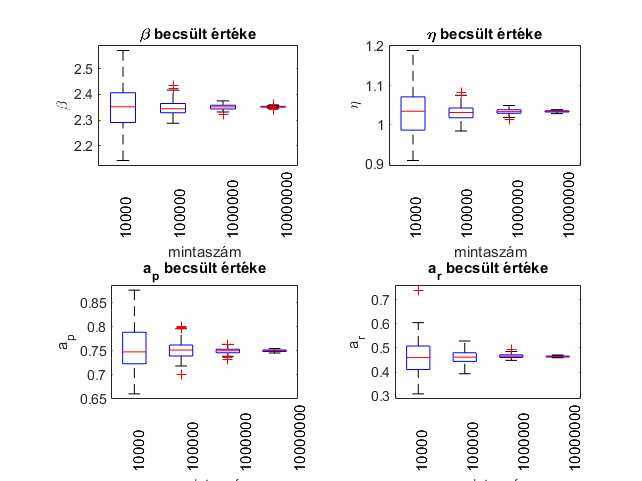

figure 
limit = 1000;
subplot(2,2,1)
%boxplot(data.beta(data.sampleSize>limit,:),data.sampleSize(data.sampleSize>limit,:),"LabelOrientation",'inline')
boxplot(data_paralell.beta(data_paralell.sampleSize>limit,:),data_paralell.sampleSize(data_paralell.sampleSize>limit,:),"LabelOrientation",'inline')
title("\beta becsült értéke")
ylabel("\beta")
xlabel("mintaszám")
subplot(2,2,2)
%boxplot(data.eta(data.sampleSize>limit,:),data.sampleSize(data.sampleSize>limit,:),"LabelOrientation",'inline')
boxplot(data_paralell.eta(data_paralell.sampleSize>limit,:),data_paralell.sampleSize(data_paralell.sampleSize>limit,:),"LabelOrientation",'inline')
title("\eta becsült értéke")
ylabel("\eta")
xlabel("mintaszám")
subplot(2,2,3)
%boxplot(data.ap(data.sampleSize>limit,:),data.sampleSize(data.sampleSize>limit,:),"LabelOrientation",'inline')
boxplot(data_paralell.ap(data_paralell.sampleSize>limit,:),data_paralell.sampleSize(data_paralell.sampleSize>limit,:),"LabelOrientation",'inline')
title("a_{p} becsült értéke")
ylabel("a_{p}")
xlabel("mintaszám")
subplot(2,2,4)
%boxplot(data.ar(data.sampleSize>limit,:),data.sampleSize(data.sampleSize>limit,:),"LabelOrientation",'inline')
boxplot(data_paralell.ar(data_paralell.sampleSize>limit,:),data_paralell.sampleSize(data_paralell.sampleSize>limit,:),"LabelOrientation",'inline')
title("a_{r} becsült értéke")
ylabel("a_{r}")
xlabel("mintaszám")

variance_beta = sqrt(var(data.beta(data.sampleSize == 10000000)))

variance_beta = 0.0030

variance_eta = sqrt(var(data.eta(data.sampleSize == 10000000)))

variance_eta = 0.0022

variance_ap = sqrt(var(data.ap(data.sampleSize == 10000000)))

variance_ap = 0.0026

variance_ar = sqrt(var(data.ar(data.sampleSize == 10000000)))

variance_ar = 0.0032

avg_var_sqrt = (variance_ar+ variance_ap+variance_eta+variance_beta)/4

avg_var_sqrt = 0.0027

% modified values
variance_beta = sqrt(var(rmmissing(data_paralell.beta(data_paralell.sampleSize == 10000000))))

variance_beta = 0.0033

variance_eta = sqrt(var(rmmissing(data_paralell.eta(data_paralell.sampleSize == 10000000))))

variance_eta = 0.0023

variance_ap = sqrt(var(rmmissing(data_paralell.ap(data_paralell.sampleSize == 10000000))))

variance_ap = 0.0020

variance_ar = sqrt(var(rmmissing(data_paralell.ar(data_paralell.sampleSize == 10000000))))

variance_ar = 0.0027

avg_var_sqrt = (variance_ar+ variance_ap+variance_eta+variance_beta)/4

avg_var_sqrt = 0.0026

data2 = readtable("results\single_core_result.csv");

data2.avg_run = data2.runTimeInMs./data2.sampleSize;
data2.run(:) = "serial";

figure
subplot(1,2,1)
%boxplot(data2.runTimeInMs,data2.sampleSize,"LabelOrientation",'inline')
boxplot(data_serial.runTimeInMs,data_serial.sampleSize,"LabelOrientation",'inline')
set(gca, 'YScale', 'log')
title("Soros futási idők")

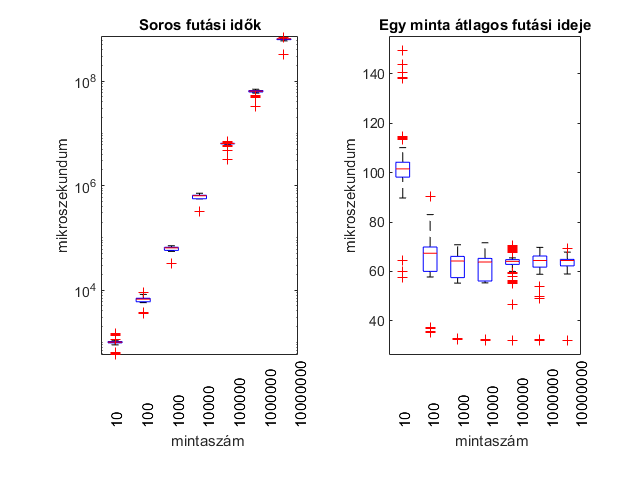

set(gca, 'YScale', 'log')
ylabel("mikroszekundum")
xlabel("mintaszám")
subplot(1,2,2)
%boxplot(data2.avg_run,data2.sampleSize,"LabelOrientation",'inline')
boxplot(data_serial.avg_run,data_serial.sampleSize,"LabelOrientation",'inline')
title("Egy minta átlagos futási ideje")
ylabel("mikroszekundum")
xlabel("mintaszám")


full = cat(1,data_paralell(data_paralell.sampleSize>100,:),data_serial(data_serial.sampleSize>100,:));

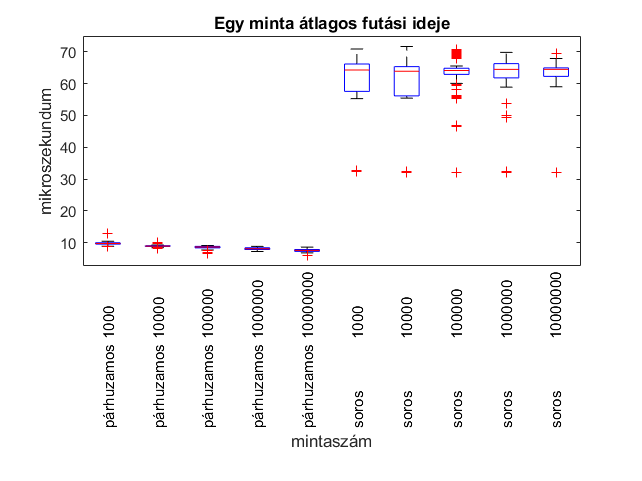

figure Name 'Összehasonlítás'
boxplot(full.avg_run,{full.run,full.sampleSize},"LabelOrientation",'inline');
title("Egy minta átlagos futási ideje")
ylabel("mikroszekundum")
xlabel("mintaszám")

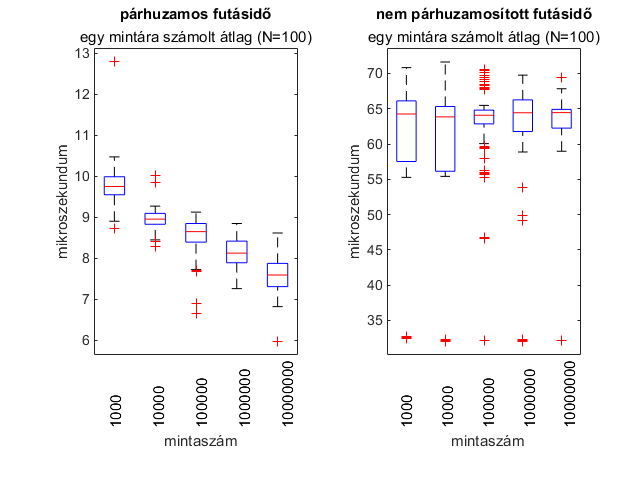

figure Name 'Szeparált összehasonítás'
subplot(1,2,1)
boxplot(data_paralell.avg_run(data_paralell.sampleSize>100,:),...
    data_paralell.sampleSize(data_paralell.sampleSize>100,:),"LabelOrientation",'inline')
title("párhuzamos futásidő","egy mintára számolt átlag (N=100)")
xlabel mintaszám
ylabel mikroszekundum
subplot(1,2,2)
boxplot(data_serial.avg_run(data_serial.sampleSize>100,:),...
    data_serial.sampleSize(data_serial.sampleSize>100,:),"LabelOrientation",'inline')
title("nem párhuzamosított futásidő","egy mintára számolt átlag (N=100)")
xlabel mintaszám
ylabel mikroszekundum

avg_run_parralel = mean(data_paralell.avg_run)

avg_run_parralel = 20.2677

avg_run_serial = mean(data_serial.avg_run)

avg_run_serial = 68.4599

avg_run_parralel_nbias = mean(data_paralell.avg_run(data_paralell.sampleSize>100))

avg_run_parralel_nbias = 8.7097

avg_run_serial_nbias = mean(data_serial.avg_run(data_serial.sampleSize>100))

avg_run_serial_nbias = 61.5691

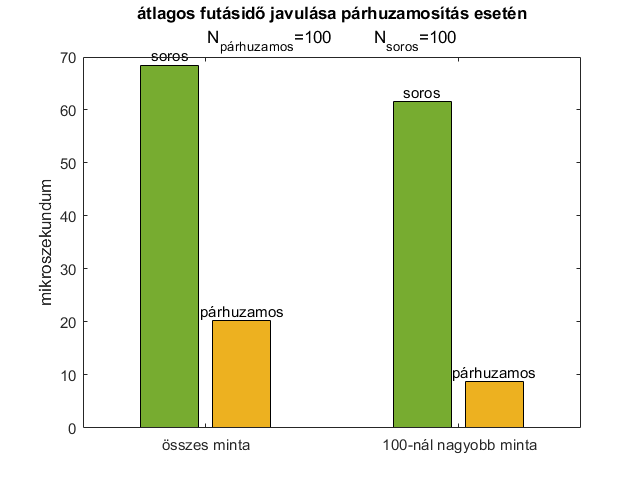

hB = bar([avg_run_serial avg_run_parralel;avg_run_serial_nbias avg_run_parralel_nbias]);
title("átlagos futásidő javulása párhuzamosítás esetén","N_{párhuzamos}=100         N_{soros}=100")
ylabel mikroszekundum
set(hB(1),"FaceColor",'#77AC30');
set(hB(2),"FaceColor",'#EDB120');
set(gca, 'XTickLabel',{'összes minta', ' 100-nál nagyobb minta'})
labels = {'soros','párhuzamos','soros','párhuzamos'};
hT=[];              % placeholder for text object handles
for i=1:length(hB)  % iterate over number of bar objects
   hT=[hT,text(hB(i).XData+hB(i).XOffset,hB(i).YData,labels(:,i), ...
          'VerticalAlignment','bottom','horizontalalign','center')];
end

improvement = avg_run_serial_nbias/avg_run_parralel_nbias

improvement = 7.0690